# 繪圖軟體應用 第14周(12/11)

# M_Map

## Netcdf : Network Common Data Form

[https://www.google.com/search?q=Netcdf&spell=1&sa=X&ved=2ahUKEwjFuKD59azmAhWXy4sBHV4_AL4QBSgAegQICxAp&biw=1280&bih=913](https://www.google.com/search?q=Netcdf&spell=1&sa=X&ved=2ahUKEwjFuKD59azmAhWXy4sBHV4_AL4QBSgAegQICxAp&biw=1280&bih=913)

clear;clc
lookfor netcdf %查詢函式說明書

nccreate                       - Create variable in NetCDF file.
ncdisp                         - Display contents of a NetCDF source in command window.
ncinfo                         - Return information about a NetCDF source.
ncread                         - Read variable data from a NetCDF source.
ncreadatt                      - Read attribute value from a NetCDF source.
ncwrite                        - Write data to NetCDF file.
ncwriteatt                     - Write attribute to NetCDF file.
ncwriteschema                  - Add NetCDF schema definitions to NetCDF file.


到 [ftp://140.121.165.44/pub/graphic_class/](ftp://140.121.165.44/pub/graphic_class/)

選取 

ssc.nc 

和 

2012070200_2012070300_daily-ifremer-L3-MWF-GLO-20120704102056-01.0.nc

help ncdisp

 ncdisp Display contents of a NetCDF source in command window.
 
     ncdisp(FILENAME) displays the groups, dimensions, variable definitions
     and all attributes in the NetCDF file FILENAME as text in the command
     window.
 
     ncdisp(OPENDAP_URL) displays information from an OPeNDAP NetCDF data
     source.
 
     ncdisp(SOURCE, LOCATION) displays information about the variable or
     group specified by the string LOCATION in SOURCE, which can either be
     a filename or an OPeNDAP URL. Set LOCATION to '/' to display entire
     file contents.
 
     ncdisp(SOURCE, LOCATION, MODESTR) displays the contents of the
     LOCATION according to the value of MODESTR. Valid values for MODESTR
     are:
 
      'min'  - display variable definitions only. 
 
      'full' - display dimensions, attributes and variable definitions.
               This is the default value.
 
 
     Example: Visually insp


ncdisp('sss.nc') %顯示內容

Source:
           C:\00781035\sss.nc
Format:
           classic
Global Attributes:
           Title        = 'sea surface salinity (SSS)'
           Comments     = 'Aquarius SSS objectively interpolated onto a regular 0.5x0.5 grid'
           Week         = 'Julian 22 - 28, 2015'
           Institution  = 'IPRC'
           DataSource   = 'Aquarius L2 V4.0'
           Notes        = 'http://iprc.soest.hawaii.edu/users/oleg/oisss/glb/Technical_Notes.pdf'
           CreationDate = '2015/08/20 14:08:56'
           CreatedBy    = 'oleg'
Dimensions:
           time      = 1
           latitude  = 360
           longitude = 720
Variables:
    time     
           Size:       1x1
           Dimensions: time
           Datatype:   single
           Attributes:
                       long_name = 'first day of the week over which Aquarius data have been collected'
                       units     = 'Julian days since December 31, 2010'
                       axis      = 'T'
    latitude 
       

Dimensions:

           time      = 1

           latitude  = 360

           longitude = 720

           Size:       720x360x1

           Dimensions: longitude,latitude,time

           Datatype:   single

           Attributes:

                       long_name  = 'sea surface salinity'

                       units      = 'psu'

                       _FillValue = -9999

ncinfo('sss.nc') 

ans = struct with fields:
      Filename: 'C:\00781035\sss.nc'
          Name: '/'
    Dimensions: [1×3 struct]
     Variables: [1×4 struct]
    Attributes: [1×8 struct]
        Groups: []
        Format: 'classic'


% clear;clc
help ncread % Read variable data from a NetCDF source.

 ncread Read variable data from a NetCDF source.
 
     VARDATA = ncread(FILENAME,VARNAME) reads data from the variable
     VARNAME in the NetCDF file FILENAME.
 
     VARDATA = ncread(OPENDAP_URL,VARNAME) reads data from the variable
     VARNAME from an OPeNDAP NetCDF data source.
 
     VARDATA = ncread(SOURCE,VARNAME,START,COUNT) 
     VARDATA = ncread(SOURCE,VARNAME,START,COUNT,STRIDE) reads data from
     VARNAME beginning at the location given by START from SOURCE, which
     can either be a filename or an OPeNDAP URL. For an N-dimensional
     variable START is a vector of 1-based indices of length N specifying
     the starting location. COUNT is also a vector of length N specifying
     the number of elements to read along corresponding dimensions. If a
     particular element of COUNT is Inf, data is read until the end of that
     dimension. The optional argument STRIDE specifies the inter


lon = ncread('sss.nc','longitude'); %一個大小是720的行向量
lon(1)

ans = single
-179.7500


lat = ncread('sss.nc','latitude');%一個大小是360的行向量
lat(end)

ans = single
89.7500

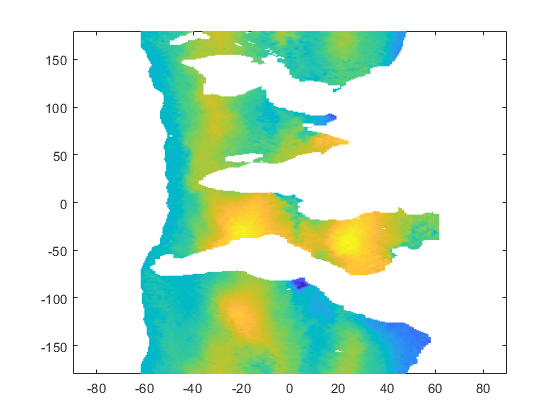


sss = ncread('sss.nc','sss');
figure(1)
pcolor(lat,lon,sss);shading interp

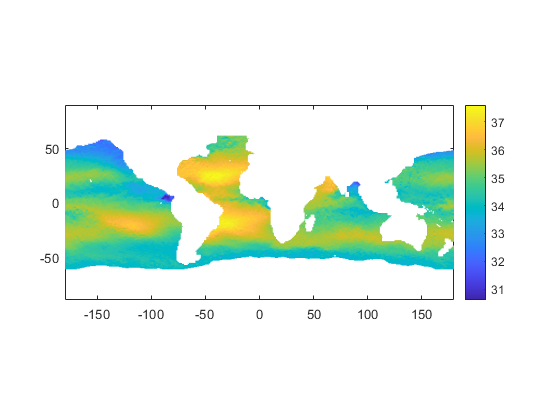


[xlat,ylon] = meshgrid(lat,lon);
figure(2)
pcolor(ylon,xlat,sss);shading interp;axis('image');
colorbar;

---------------------------------------------------------------------------------------------------------

到 [ftp://140.121.165.44/pub/graphic_class/](ftp://140.121.165.44/pub/graphic_class/)

選取 

sample_2016.nc

clear;clc
ncdisp('sample_2016.nc') %顯示內容

Source:
           C:\00781035\sample_2016.nc
Format:
           classic
Global Attributes:
           title               = 'AVHRR PATHFINDER SEA SURFACE TEMPERATURE'
           temporal_resolution = 'Five Day Average'
           spatial_resolution  = '0.5 degree'
           creation_date       = 'Thu Aug 15 10:40:39 2002'
           originating_center  = 'NASA JPL PO.DAAC'
           WOCE_Version        = '3.0-PF4.1'
           Conventions         = 'COARDS/WOCE'
Dimensions:
           time      = 1
           depth     = 1
           latitude  = 360
           longitude = 720
Variables:
    woce_date
           Size:       1x1
           Dimensions: time
           Datatype:   int32
           Attributes:
                       long_name      = 'WOCE date'
                       units          = 'yyyymmdd'
                       data_min       = 19900101
                       data_max       = 19900105
                       FORTRAN_format = 'I8'
                       time_interval

lat2 = ncread('sample.nc','latitude');
lon2 = ncread('sample.nc','longitude');

---------------------------------------------------------------------------------------------------------

到 [ftp://140.121.165.44/pub/graphic_class/](ftp://140.121.165.44/pub/graphic_class/)

選取 

extract_wind.m (羅老師自己的使用範例)

到 [ftp://140.121.165.44/pub/graphic_class/](ftp://140.121.165.44/pub/graphic_class/)

選取 

mexnc_install.docx 解說

到M_Map下載最新版

## Announcing M_Map v1.4k!

點擊 [zip archive](http://www.eos.ubc.ca/~rich/m_map1.4.zip) 下載

`將`m_map`檔案夾放置於`Matlab`的目錄中。`

`例如``：``將`m_map1.4`檔案夾拷貝到`

C:\Program Files\MATLAB\R2019b

`五個不同解析度的全球海岸線資料檔案：`

gshhs_c.b`、`gshhs_f.b`、`gshhs_h.b`、`gshhs_i.b`與`gshhs_l.b

[ftp://140.121.165.44/pub/graphic_class/m_map/](ftp://140.121.165.44/pub/graphic_class/m_map/)

`拷貝到`C:\Program Files\MATLAB\R2019b\m_map1.4\m_map\private

將以上5個檔案放到C:\00781035\m_map1.4.zip\m_map\private

clear;clc
help m_coast


m_coast not found.

Use the Help browser search field to search the documentation, or
type "help help" for help command options, such as help for methods.



`修改`C:\Program Files\MATLAB\R2019b\toolbox\local\

`的`pathdef.m`檔案，加入`m_map`的路徑，如下：`matlabroot,'\m_map1.4\m_map;', ...

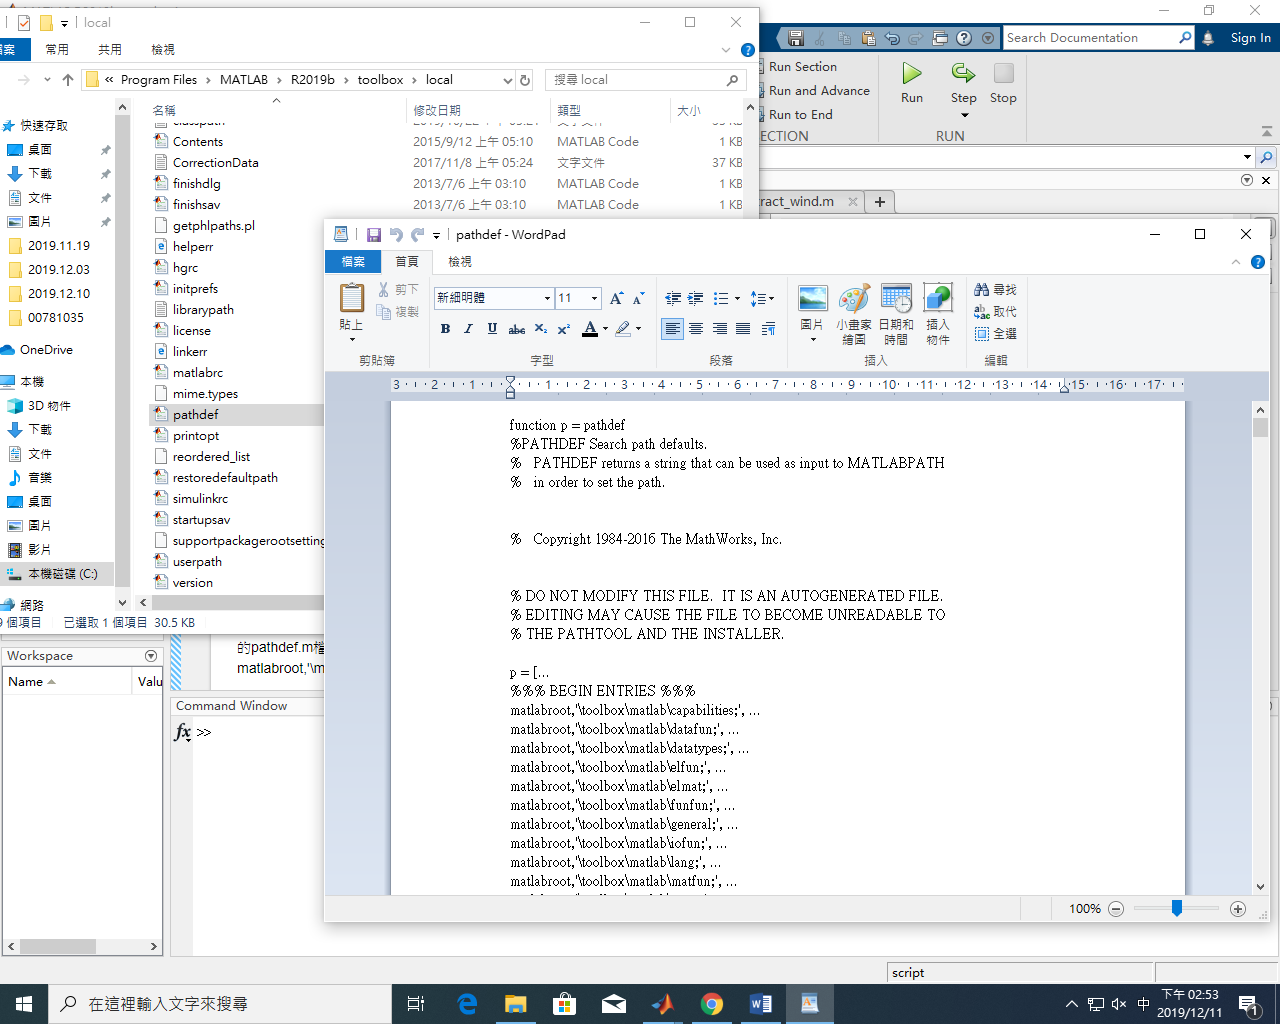

clear;clc
help m_coast


m_coast not found.

Use the Help browser search field to search the documentation, or
type "help help" for help command options, such as help for methods.

